# Tongue vs Lip Raw Fluorescence

We compare tongue and lip within each subect at each of the different excitation wavelengths.  We use the maximum intensity for each wavelength.

In a separate notebook we should show the reflectance level and compare it with the fluorescence level.  

See also

ieInit;

## Set up the data management

[T,dataDir] = oeDatabaseCreate;
wave = 500:700;

## Tongue spectra

I like normalizing at 550 nm for all of them.  Or some fixed wavelength.  The raw spectra for tongue and lip are of course different.  Just look at your tongue and lip.  

There is keratin on the dorsal part of the tongue, where we measured, that gives it that white shiny appearance?  

You can see blood ripples in all of these.  As plotted we are including multiple light levels.  When we normalize they all come together in the 500-600 band, but there is residual scaling in the 600-700 band.  We think that is due to food on the tongue.  Maybe chlorophyll? Maybe differences in bacteria (porphyrins).

Joyce has a porphyrin cholorphyll love story with light and evolution.

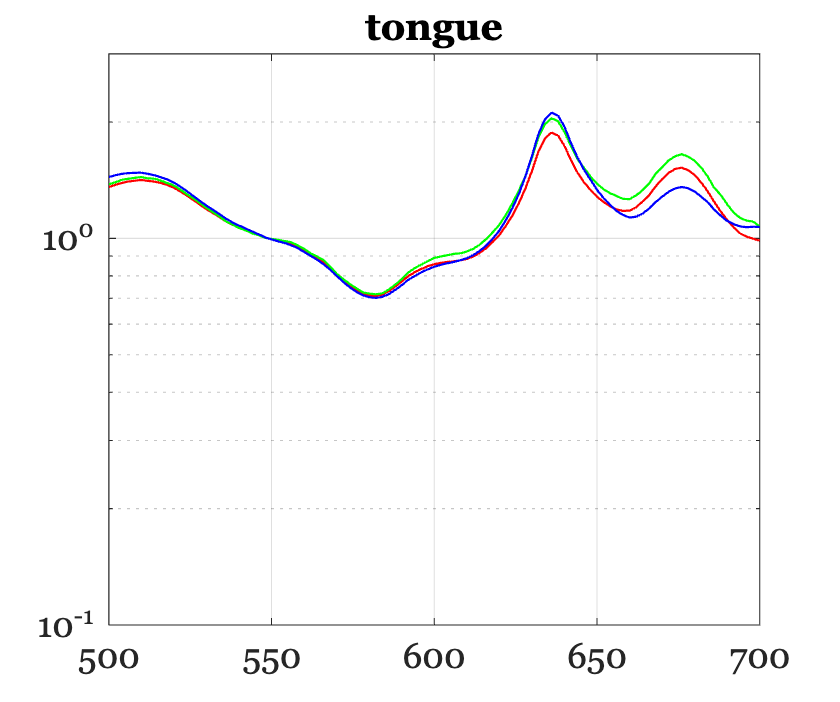

files = ieTableGet(T,'subject','J',...
    'substrate','tongue', ...
    'e wave',405);
data = zeros(numel(wave),numel(files));

ieNewGraphWin;
for ii=1:numel(files)
    tmp = ieReadSpectra(fullfile(dataDir,files{ii}),wave); 
    data (:,ii) = tmp(:)/max(tmp(50));
    semilogy(wave,data); hold on;
end
title('tongue'); grid on; set(gca,'ylim',[0.1 3]);

## Lip

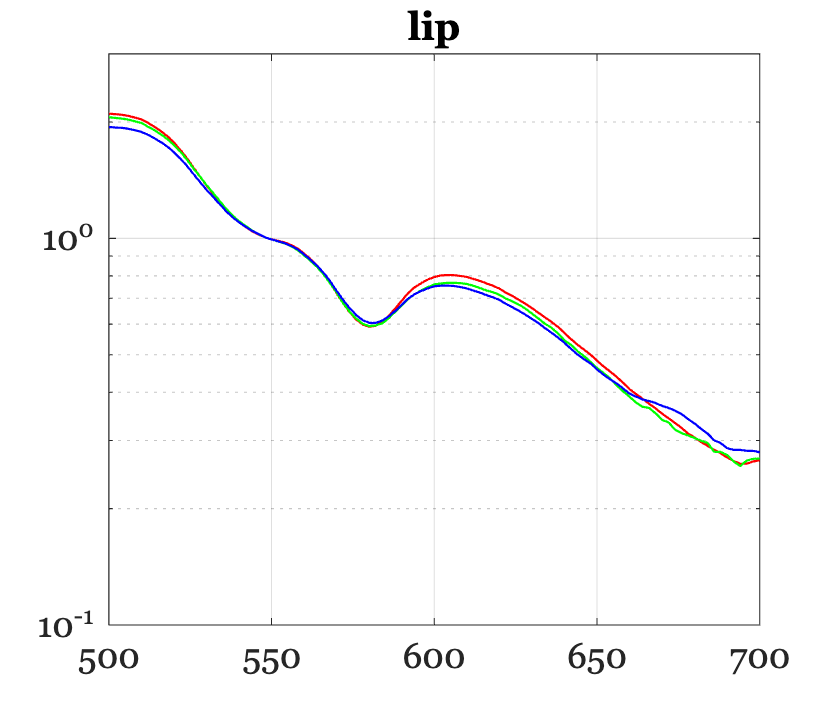

files = ieTableGet(T,'subject','J',...
    'substrate','lip',...
    'e wave',405);
data = zeros(numel(wave),numel(files));

ieNewGraphWin;
for ii=1:numel(files)
    tmp = ieReadSpectra(fullfile(dataDir,files{ii}),wave); 
    data (:,ii) = tmp(:)/max(tmp(50));
    semilogy(wave,data); hold on;
end
title('lip'); grid on; set(gca,'ylim',[0.1 3]);